# Sistemas de Visión Artificial

# **Práctica 1. Parte 1. Adquisición de Imágenes**

**Autor(es): Alejandro Fernandez Ambros, Cristina Martinez Toledo**

**Fecha: 28/09/2026**

El objetivo principal de esta práctica es conseguir adquirir imágenes y vídeos con Matlab y realizar pequeños ajustes y operaciones sobre la grabación.

Las tareas a realizar son las siguientes: 

- En primer lugar debe asegurarse de que tiene instaladas las toolboxes "Image Acquisition Toolbox" e "Image Processing Toolbox".

- Una vez instalados y conectada la cámara, ejecute "imageAcquisitionExplorer". Si la página aparece vacía, pinche en "Don't see your device?" y siga los pasos para instalar el "Support Package" correspondiente. En general es suficiente con el adaptador básico "Image Acquisition Toolbox Support Package for OS Generic Video Interface".

- Lea la documentación de Matlab en [https://es.mathworks.com/help/imaq/get-started-with-image-acquisition-explorer.html](https://es.mathworks.com/help/imaq/get-started-with-image-acquisition-explorer.html) sobre la aplicación y visualice el vídeo que contiene la página. 

- Seleccione la cámara y experimente con las distintas opciones ofrecidas por la interfaz: configure un formato de vídeo de tamaño diferente al que aparece por defecto (en la esquina superior izquierda), seleccione una ROI, cambie brillo, contraste, etc.

- Realice la captura de una imagen en color y otra en grayscale (cambiando el "Color Space") guardándolas como "Workspace Variables" y compruebe que las variables generadas en Matlab tienen las dimensiones adecuadas (según el formato de vídeo elegido y el espacio de color).

- Configure el espacio de color a "rgb", y la captura de vídeo en modo continuo a un fichero, y exporte (Export) un script para la grabación de vídeo (Generate record script). Analice las instrucciones del script, observando cómo se cambia cada parámetro y realice alguna modificación sobre él.

-  Cierre el "imageAcquisitionExplorer" y ejecute en Matlab el script generado. Es imprescindible cerrar antes el "imageAcquisitionExplorer" ya que solo puede tener abierta una aplicación que controle de la cámara. En caso contrario, se obtiene un mensaje de error. Este error ocurrirá siempre que una aplicación esté utilizando la cámara y se ejecute otra que deba utilizarla.

La **entrega correspondiente a la parte 1 de la práctica 1 **será el mlx exportado del imageAcquisitionExplorer, configurado para grabación de vídeo, que incluya la modificación de varios parámetros de la captura (ROI, brillo, etc...). Se copiará a continuación de este fichero, incluyendo en la parte superior, en el espacio reservado para ello, el nombre de los autores y la fecha.

% Grabador de vídeo


# Auto-generated by Image Acquisition Explorer

Generated in MATLAB R2026a on 28-Sep-2026 09:04:19

## Connect to Device

Create connection to the device using the specified adaptor with the specified format.

v = videoinput("winvideo", 1, "YUY2_640x360");

## Configure Device Properties

Configure videoinput properties to prepare for acquisition.

v.ReturnedColorspace = "rgb";
v.ROIPosition = [81 22 488 311];

## Configure Device-Specific Properties

Configure properties that are specific to this device.

src = getselectedsource(v);
src.Brightness = -37;
src.Contrast = 56;
src.Gamma = 181;
src.Hue = -30;
src.Saturation = 84;
src.Sharpness = 1;
src.WhiteBalance = 4563;
src.WhiteBalanceMode = "manual";

## Configure File Logging

Configure the device to log video to disk. Set the desired file location and name.

filelocation = "C:\Users\Usuario\Desktop\vision artificial\2026-27.SVA_Practica1";
filename = "recording1.avi";
fullFilename = fullfile(filelocation, filename);

% Create and configure the video writer
logfile = VideoWriter(fullFilename, "Motion JPEG AVI");

% Configure the device to log to disk using the video writer
v.LoggingMode = "disk";
v.DiskLogger = logfile;

## Record Continuous Video Data

Record video data continuously.

v.FramesPerTrigger = Inf;
start(v);

% Use INPUT to pause before ending acquisition.
input("Press ENTER to end acquisition.");
stop(v);

% Wait for all frames to be written to disk
while v.FramesAcquired ~= v.DiskLoggerFrameCount
    pause(.1);
end

## Show Recording

View the recorded video.

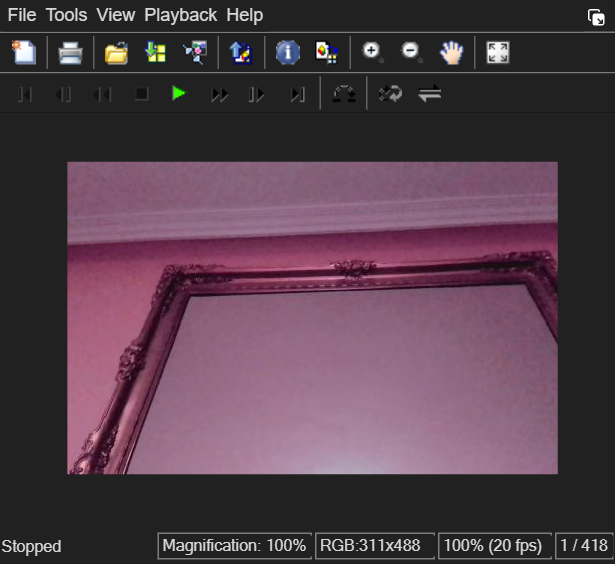

reader = VideoReader(fullFilename);
videoData = read(reader);
implay(videoData);

## Clean Up

Delete the videoinput object and clear variables from the workspace.

delete(v)
clear src v
